# Potential Field Visualizations

Constructing the Potential Field

point_spacing = 0.2;

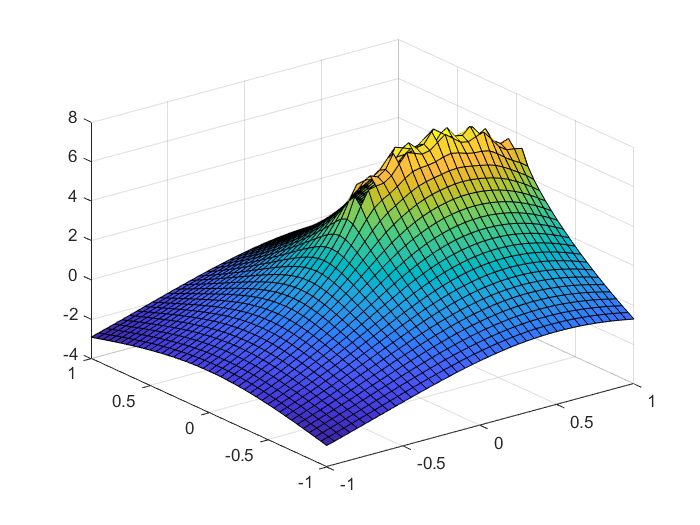

bounds = -1:0.05:1;
[x, y] = meshgrid(bounds, bounds);

potential_func = make_potential_line([0, 0], [1, 0], point_spacing);
surf(x, y, potential_func(x, y));

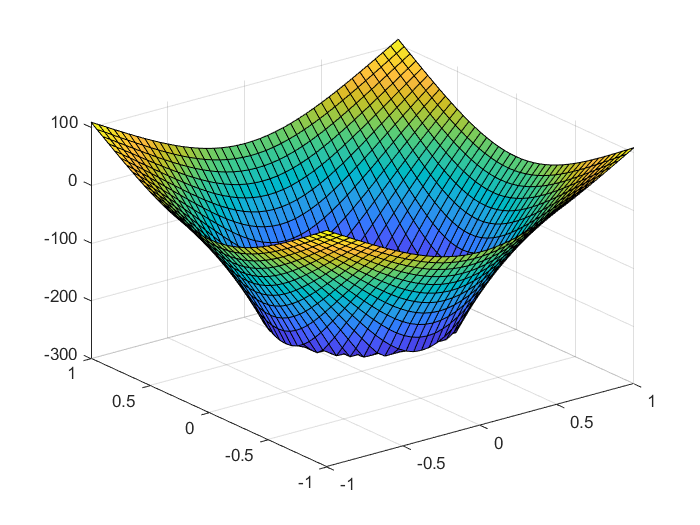

potential_func = make_potential_BoB([0, 0], 0.5, point_spacing);
surf(x, y, potential_func(x, y));

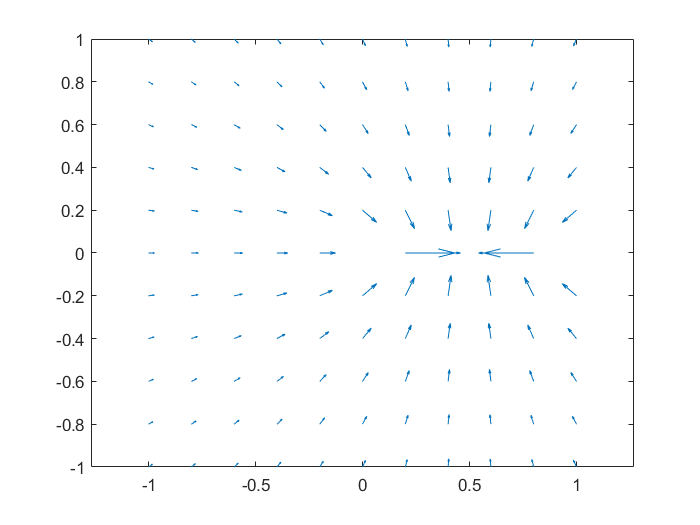

bounds = -1:0.2:1;
[x, y] = meshgrid(bounds, bounds);
grad_func = make_gradient_line([0, 0], [1, 0], point_spacing);
grad_points = grad_func(x, y);
quiver(x, y, grad_points(:,:,1), grad_points(:,:,2))
axis equal

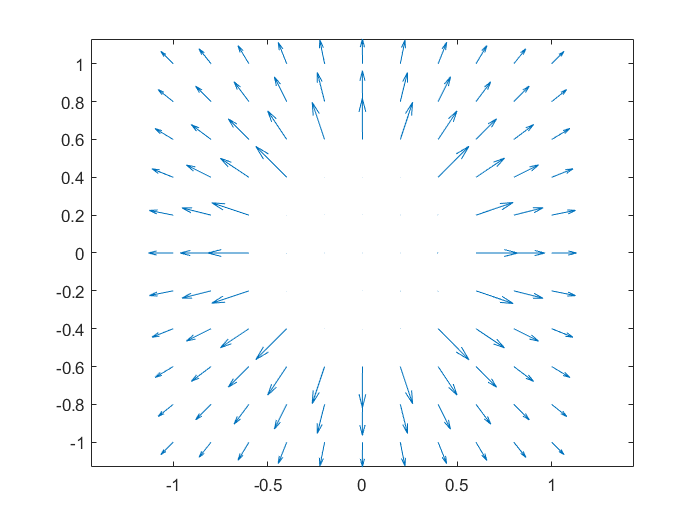

grad_func = make_gradient_BoB([0, 0], 0.5, point_spacing);
grad_points = grad_func(x, y);
quiver(x, y, grad_points(:,:,1), grad_points(:,:,2))
axis equal

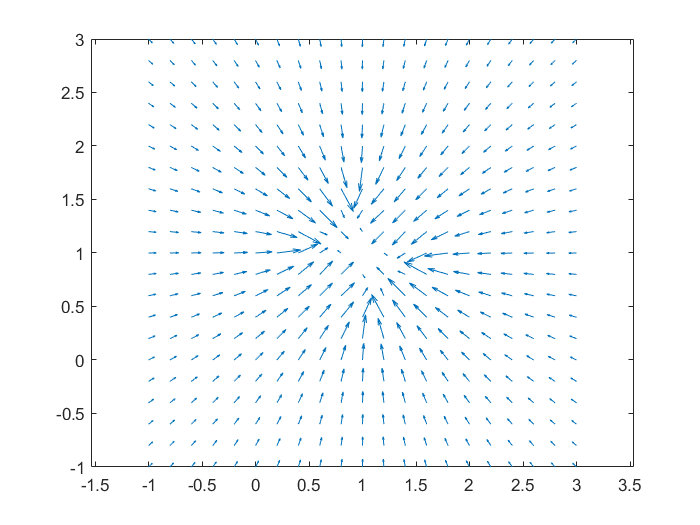

[potential_func, grad_func] = make_square(1, [1, 1], pi/4, point_spacing);

bounds = -1:0.2:3;
[x, y] = meshgrid(bounds, bounds);
grad_points = grad_func(x, y);
quiver(x, y, grad_points(:,:,1), grad_points(:,:,2))
axis equal

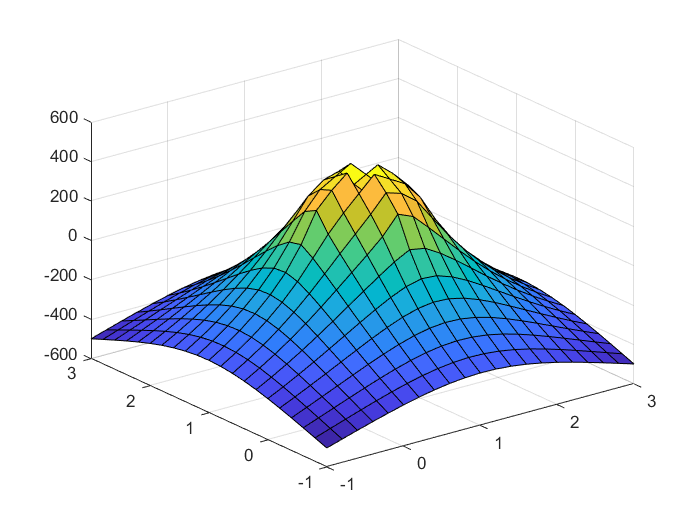


surf(x, y, potential_func(x, y));

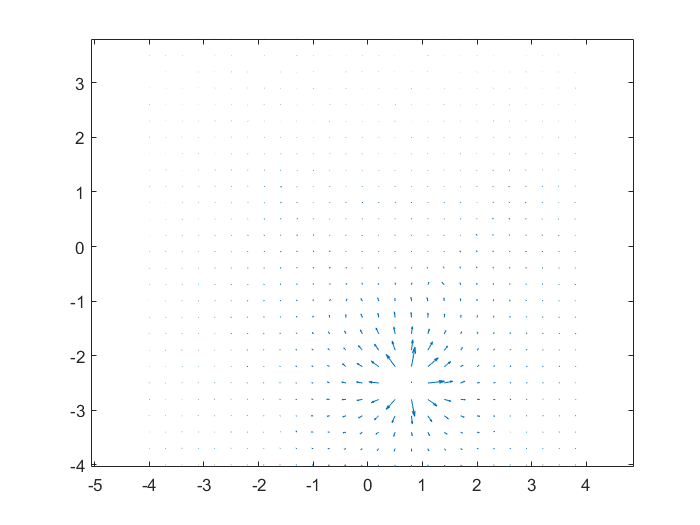

[potential_func, grad_func] = make_hardcoded_guantlet(point_spacing, 20);

bounds = -4:0.3:4;
[x, y] = meshgrid(bounds, bounds);
grad_points = grad_func(x, y);
quiver(x, y, grad_points(:,:,1), grad_points(:,:,2))
axis equal

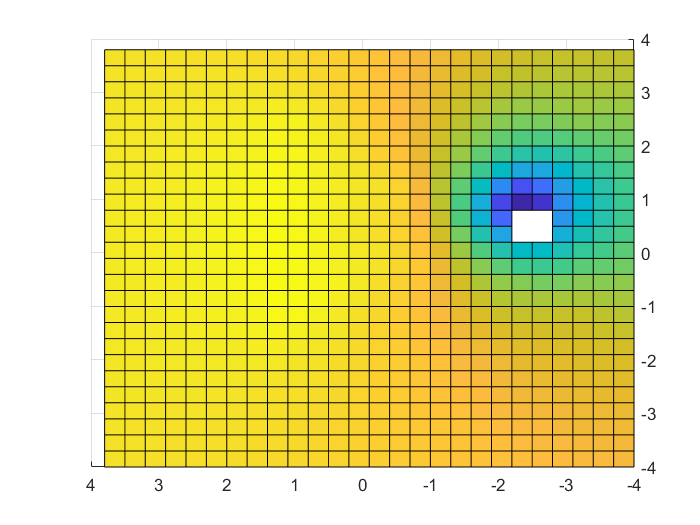


surf(x, y, potential_func(x, y));

grad_func(0,0)

ans = ans(:,:,1) =

   -6.2815


ans(:,:,2) =

   19.9845


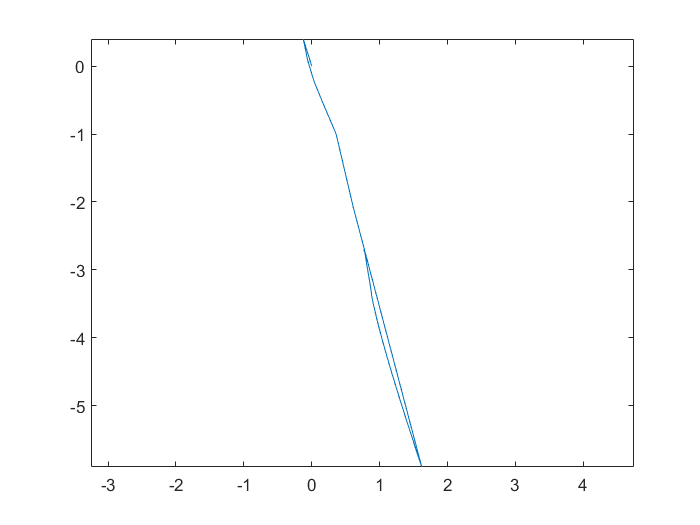

r_0 = [0, 0];
lambda = 1/50;
delta = 0.9;
tolerance = 1e-3;
max_steps = 1000;

path = gradient_descent(grad_func, r_0, lambda, delta, tolerance, max_steps);
plot(path(:, 1), path(:, 2));
axis equal

path(end, :)

ans =     0.7674   -2.7351
